% Series Compensation
% Course: Energy Systems Analysis - Dr. Fotuhi-Firuzabad
% Student: Vahid Hamzeh - 402101577

clc; clear; close all;

% System Parameters
V_base = 765e3;      
L_total = 360;        
f = 50;

% Lossless Line Parameters
R_prime = 0;          
X_prime = 0.38;       
B_prime = 2.8e-6;    

z = 1j*X_prime;
y = 1j*B_prime;
gamma = sqrt(z*y);    
Zc = sqrt(z/y);       
beta = imag(gamma);   

% Locations for Series Capacitor
Loc_fractions = [1/6, 1/3, 1/2, 2/3];
Loc_labels = {'L/6', 'L/3', 'L/2', '2L/3'};

% Target: Increase Power Transfer Capability by 2%
Target_Increase_Pct = 2.0; 
Scale_Factor = 1 + (Target_Increase_Pct/100);

% Load Condition 
P_load = 561.3; % MW
Q_load = P_load * tan(acos(0.92));
Vs_mag = 1.0;   % p.u.

% Base Case Calculation
T_un = [cos(beta*L_total), 1j*Zc*sin(beta*L_total); 1j/Zc*sin(beta*L_total), cos(beta*L_total)];
B_un = imag(T_un(1,2));

I_sc_un_kA = (V_base / B_un) / 1000;

fprintf('Uncompensated Short Circuit Current: %.2f kA\n', I_sc_un_kA);

Uncompensated Short Circuit Current: 5.72 kA


fprintf('Target B_eq: %.2f Ohm (Original: %.2f Ohm)\n', B_un/Scale_Factor, B_un);

Target B_eq: 131.06 Ohm (Original: 133.68 Ohm)


% Optimization & Plotting Loop
figure('Name', 'Series Compensation Voltage Profiles', 'Color', 'w', 'Units', 'normalized', 'Position', [0.1 0.1 0.6 0.8]);
t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Voltage Profile: Before vs. After Series Compensation (10km Step)');
xlabel(t, 'Distance (km)');
ylabel(t, 'Voltage (p.u.)');

fprintf('%-6s | %-8s | %-8s | %-10s | %-10s | %-8s\n', ...
    'Loc', 'Xc(Ohm)', 'Deg(%)', 'V_drop(kV)', 'Angle(deg)', 'Isc_Ratio');


--- Series Compensation Results ---


Loc    | Xc(Ohm)  | Deg(%)   | V_drop(kV) | Angle(deg) | Isc_Ratio


---------------------------------------------------------------


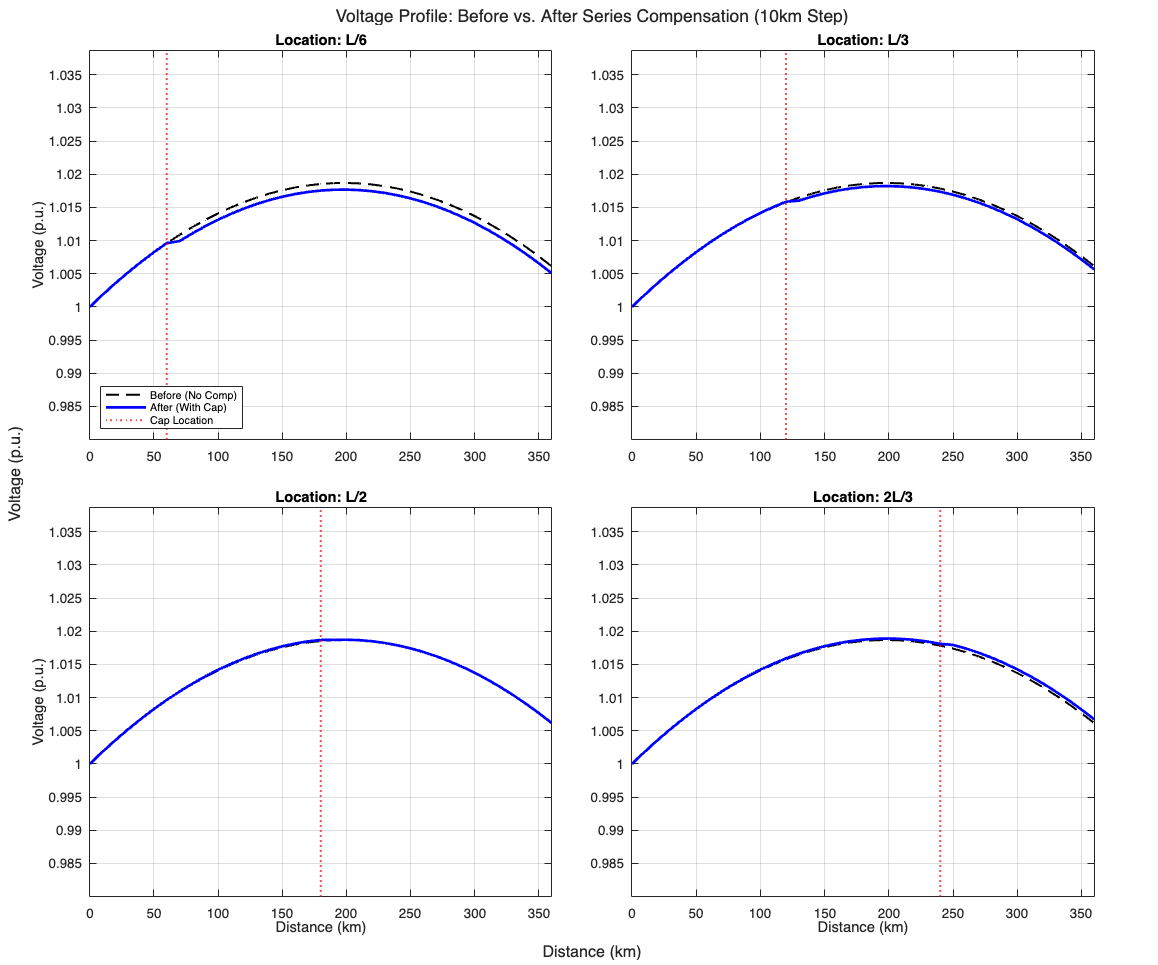

L/6    | 2.76     | 2.02     | 2.13       | 7.18       | 1.0200  
L/3    | 2.72     | 1.99     | 2.01       | 7.18       | 1.0200  
L/2    | 2.71     | 1.98     | 1.96       | 7.18       | 1.0200  
2L/3   | 2.72     | 1.99     | 1.98       | 7.17       | 1.0200  


for k = 1:length(Loc_fractions)
    x_c = Loc_fractions(k) * L_total;
    
 
    fun = @(xc) solve_B_param(xc, x_c, L_total, Zc, beta, B_un/Scale_Factor);
    Xc_opt = fzero(fun, 10); 
    
    Deg_Comp = (Xc_opt / (X_prime * L_total)) * 100;
    
    % Calculate Operating Points
    [T_eq, ~] = get_ABCD_series(L_total, x_c, Xc_opt, Zc, beta);
    
    % Solve Power Flow for 561.3 MW
    S_load = (P_load + 1j*Q_load)*1e6;
    eqn = @(v) abs(T_eq(1,1)*v + T_eq(1,2)*conj(S_load/v)) - Vs_mag*V_base;
    Vr_sol = fsolve(eqn, V_base, optimset('Display','off'));
    Ir_sol = conj(S_load/Vr_sol);
    
    % Calculate Angle Delta (Sending - Receiving)
    Vs_phasor = T_eq(1,1)*Vr_sol + T_eq(1,2)*Ir_sol;
    Delta_deg = angle(Vs_phasor) * 180/pi; 
    
    % Get Profiles (Before & After)
    % Uncompensated (Before)
    [dist_un, V_un, ~, ~] = get_profile(L_total, -1, 0, Zc, beta, P_load, Q_load, V_base, Vs_mag);
    
    % Compensated (After)
    [dist_comp, V_comp, I_mag_comp, I_cap_mag] = get_profile(L_total, x_c, Xc_opt, Zc, beta, P_load, Q_load, V_base, Vs_mag);
    
   
    V_drop_kV = (I_cap_mag * 1000 * Xc_opt) / 1000; 
    
    B_new = imag(T_eq(1,2));
    I_sc_new_kA = (V_base / B_new) / 1000;
    I_sc_ratio = I_sc_new_kA / I_sc_un_kA;
    
    % Print
    fprintf('%-6s | %-8.2f | %-8.2f | %-10.2f | %-10.2f | %-8.4f\n', ...
        Loc_labels{k}, Xc_opt, Deg_Comp, V_drop_kV, Delta_deg, I_sc_ratio);
        
    nexttile;
    hold on; grid on; box on;
    
    plot(dist_un, V_un, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Before (No Comp)');
    
    plot(dist_comp, V_comp, 'b-', 'LineWidth', 2, 'DisplayName', 'After (With Cap)');
    
    xline(x_c, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Cap Location');
    
    title(sprintf('Location: %s', Loc_labels{k}));
    if k == 3 || k == 4; xlabel('Distance (km)'); end
    if k == 1 || k == 3; ylabel('Voltage (p.u.)'); end
    xlim([0 L_total]);
    ylim([min(V_un)-0.02, max(V_un)+0.02]);
    
    if k == 1; legend('Location', 'SouthWest', 'FontSize', 8); end
end

function diff = solve_B_param(Xc, x_c, L, Zc, beta, B_target)
    [T_eq, ~] = get_ABCD_series(L, x_c, Xc, Zc, beta);
    B_calc = imag(T_eq(1,2));
    diff = B_calc - B_target;
end

function [T_eq, T_cap] = get_ABCD_series(L, x_c, Xc, Zc, beta)
    A1 = cos(beta*x_c); B1 = 1j*Zc*sin(beta*x_c);
    C1 = 1j/Zc*sin(beta*x_c); D1 = A1;
    T1 = [A1 B1; C1 D1];
    T_cap = [1, -1j*Xc; 0, 1];
    len2 = L - x_c;
    A2 = cos(beta*len2); B2 = 1j*Zc*sin(beta*len2);
    C2 = 1j/Zc*sin(beta*len2); D2 = A2;
    T2 = [A2 B2; C2 D2];
    T_eq = T1 * T_cap * T2;
end

function [dist, V_mag_pu, I_mag, I_cap_mag] = get_profile(L, x_c, Xc, Zc, beta, P, Q, Vbase, Vs_target_mag)
    S_load = (P + 1j*Q)*1e6;
    
    if x_c < 0
        T_eq = [cos(beta*L), 1j*Zc*sin(beta*L); 1j/Zc*sin(beta*L), cos(beta*L)];
        Xc = 0;
    else
        [T_eq, ~] = get_ABCD_series(L, x_c, Xc, Zc, beta);
    end
    
    eqn = @(v) abs(T_eq(1,1)*v + T_eq(1,2)*conj(S_load/v)) - Vs_target_mag*Vbase;
    Vr = fsolve(eqn, Vbase, optimset('Display','off'));
    Ir = conj(S_load/Vr);
    
    dist = 0:10:L; 
    
    V_mag_pu = zeros(size(dist));
    I_mag = zeros(size(dist));
    I_cap_mag = 0; 
    
    for i = 1:length(dist)
        d = dist(i); 
        y = L - d;   
        
        if x_c < 0 || d > x_c 
            Ay = cos(beta*y); By = 1j*Zc*sin(beta*y);
            Cy = 1j/Zc*sin(beta*y); Dy = Ay;
            Vy = Ay*Vr + By*Ir;
            Iy = Cy*Vr + Dy*Ir;
        else 
            len2 = L - x_c;
            A2 = cos(beta*len2); B2 = 1j*Zc*sin(beta*len2);
            C2 = 1j/Zc*sin(beta*len2); D2 = A2;
            V_cap_load = A2*Vr + B2*Ir;
            I_cap_load = C2*Vr + D2*Ir;
            
            V_cap_source = V_cap_load + (-1j*Xc)*I_cap_load;
            I_cap_source = I_cap_load;
            
            len_rem = x_c - d;
            Ax = cos(beta*len_rem); Bx = 1j*Zc*sin(beta*len_rem);
            Cx = 1j/Zc*sin(beta*len_rem); Dx = Ax;
            
            Vy = Ax*V_cap_source + Bx*I_cap_source;
            Iy = Cx*V_cap_source + Dx*I_cap_source;
        end
        
        V_mag_pu(i) = abs(Vy)/Vbase;
        I_mag(i) = abs(Iy)/1000; 
        
        if abs(d - x_c) < 6 
            I_cap_mag = abs(Iy)/1000; 
        end
    end
end